# ** Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

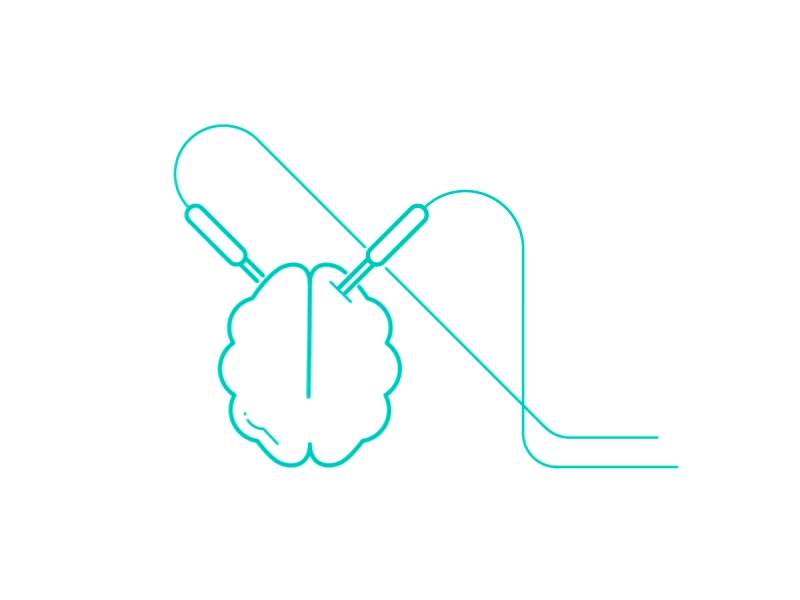

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\John\Desktop\data\raw\All_new'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 4 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false ;
Deci.DCom               = false ;
Deci.GCom               = false ; % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\John\Desktop\data\raw\AllProcessed'];        % Output Folder Directory

## 1. Trial Definitions 

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                         % Cell Array of Markers for End codes.
Deci.DT.FixUnevenStartEnd = true;
%                       ss1 ss2 ss4  L  R   Cor Incor
% Deci.DT.Markers    = {[52 53 54] [61 62] [64 65]};

Deci.DT.Markers    = {[52 53 54] [64 65]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [300 50 57 58 60];  %add probe image on/offset for RT lock                                                              % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 5];    %[-2 5]                                                                % Time of Interest, be sure to include larger window for freq

Deci.DT.Block.Markers   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'no';
Deci.PP.denoiser = false;

Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.ATR =  true;
Deci.Art.AutomatedTR = false;
Deci.ICA.Automatic = false;

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 3];

Deci.Art.AppendNewArtifacts = false;
Deci.Art.RT.locks = [4 5];
Deci.Art.RT.dominlength = true;
Deci.Art.RT.minlength = 150;
Deci.Art.RT.domaxlength = true;
Deci.Art.RT.maxlength = 3000;
Deci.Art.RT.dotwostd = false;

Deci.Art.ShowArt = false;

Deci.Art.AddComponents =  false;

## 4. Analysis

AnalysisTypes = {'DMSS_Delay'};

AnalysisList = [true ];

## 5. Plotting

## ** 6. Run**

if Deci.Step == 4
    for AnalysisLocks = find(AnalysisList)
        Deci_Wavelet;
        
        Deci.Analysis.Freq.foi           = exp(linspace(log(3),log(55),40));  %change to 80                        % Frequency of Interest
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));   % Width
        Deci.Analysis.Toi           = [-.5 3];                                % [-.5 5]                  % Time Range to save
        Deci.Analysis.Toilim        = [-2 5]; %[-2 5]
        
        eval(AnalysisTypes{AnalysisLocks})
        Deci.SubjectList        = 'gui';
        Deci.Analysis.Freq.do  = true;
        Deci.Analysis.ERP.do  = false;
        Deci.Analysis.Freq.Induced.do = false;
        Deci_Backend(Deci);
        
    end
else

    %30, 31, 46
    
    DMSS_Delay;
    
    Deci.Run.Behavior = false;
    Deci.Run.Freq =true;
    Deci.Run.ERP =false;
    Deci.Run.Extra = false; % for model, double, triplet, 2std
    
    Deci.Plot.BslRef =  'First Stim Onset';
    Deci.Plot.Lock =  'Delay Onset';
    Deci.Plot.FreqYScale = 'log';
    
    Deci.Plot.GrandAverage = true;
    Deci.Plot.GroupLevel =  false;
    Deci.Plot.Groups = {~[1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0] logical([1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0])};
    
    
    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [13 20];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [2 3];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.MTopo.do    =false;
    Deci.Plot.MTopo.Foi     = [13 30];                   % Frequency of Interest
    Deci.Plot.MTopo.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.MTopo.ToiSegs = 6;
    Deci.Plot.MTopo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =false;
    Deci.Plot.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.Square.Channel = ['Reinhart-All'];
    %{'FCz' 'Cz' 'Fz' 'CPz'};
    %['Reinhart-All'];
    %{'PO8' 'PO4', 'POz', 'PO3', 'PO7', 'O1', 'Oz', 'O2'};
    %['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Foi     =   [3 inf];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [0 .5];                   % Time of Interest
    Deci.Plot.Wire.Channel = [{'PO3'}];              % Channel of Interest
    
    Deci.Plot.Bar.do    =true;
    Deci.Plot.Bar.Foi     = [13 22];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     =  [1.5 3];                   % Time of Interest
    Deci.Plot.Bar.Channel = {'F1', 'Fz', 'F2', 'FC1', 'FCz', 'FC2', 'C2', 'Cz', 'C1', 'CP1', 'CPz', 'CP2'};
    %{'PO8' 'PO4', 'POz', 'PO3', 'PO7', 'O1', 'Oz', 'O2'}; 
    %{'FCz' 'Cz' 'Fz' 'CPz'}
    %{'PO8' 'PO4', 'POz', 'PO3', 'PO7', 'O1', 'Oz', 'O2'};            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Bsl     = [-.5 -.2];
    else
        Deci.Plot.Bsl     = [-.2 0];
    end
    
    if strcmpi(Deci.Plot.Freq.Type,'ITPC')
        Deci.Plot.Freq.Roi = 'maxmin';
    end
    
    Deci.Plot.ColorMap = fliplr(brewermap(255,'spectral')')';


   Deci.Plot.Stat.do = true;
   Deci.Plot.Stat.FPlots =  false;
   Deci.Plot.Roi = [-1 1];
   
    if  Deci.Plot.Square.do
        Omnibus = true;
        if Omnibus == true
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'relchange';
            Deci.Plot.Stat.Type = 'Anova/T-test';
        else
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType ='relchange';
        end

    elseif Deci.Plot.Topo.do || Deci.Plot.MTopo.do
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
           % Deci.Plot.BslType ='db';
        end
    elseif Deci.Plot.Wire.do
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'fdr';
         Deci.Plot.BslType ='relative';
    elseif Deci.Run.Extra
        Deci.Plot.BslType ='relchange';
    end
    Deci.Plot.Stat.twoway.do  = false;

 %   time = {[0 .5] [.5 1] [1 1.5] [1.5 2] [2 2.5] [2.5 3]};
%    for i = 1:length(time)
 %       Deci.Plot.MTopo.Toi = time{i};
%        Deci_Backend(Deci);
%    end
    
    Deci_Backend(Deci);
end

Running Deci for 3 subjects
 
----------------------
Starting Analyzor for Subject #1: DMSS031
 
Downsampling Applied
 
---Starting Condition #1: Set Size 1 Delay---
 
Applying Artifact Rejection
Final trial count is 216
 
---Starting Lock #1: First Stim Onset---
 
the input is raw data with 64 channels and 216 trials
 
---Starting Lock #2: Delay Onset---
 
the input is raw data with 64 channels and 216 trials
 
---Starting Lock #3: Rsp Onset---
 
the input is raw data with 64 channels and 216 trials
 
---Starting Condition #2: Set Size 2 Delay---
 
Applying Artifact Rejection
Final trial count is 222
 
---Starting Lock #1: First Stim Onset---
 
the input is raw data with 64 channels and 222 trials
 
---Starting Lock #2: Delay Onset---
 
the input is raw data with 64 channels and 222 trials
 
---Starting Lock #3: Rsp Onset---
 
the input is raw data with 64 channels and 222 trials
 
---Starting Condition #3: Set Size 4 Delay---
 
Applying Artifact Rejection
Final trial count is 206
 
-